1. Gauss-Newton method to fit the data

(a) Approximate the Jacobian with finite differences, as given in (9.49)

clear
clc

global Jacb2; global funy;
global t ; global Yt; global sigma; global h;

dfi_m1 = @(m) ((m(1)+ h).*exp(m(2)*t') - m(1).*exp(m(2)*t'))./(sigma*h);
dfi_m2 = @(m) (m(1).*exp((m(2)+h)*t') - m(1).*exp(m(2)*t'))./(sigma*h);

Jacb2 = @(m) [dfi_m1(m) dfi_m2(m)];



funy = @(m) (m(1)*exp(m(2)*t') - Yt')./sigma;

t = [1,2,4,5,8];
Yt = [3.2939,4.2699,7.1749,9.3008,20.259];
sigma = 0.15; h = 1e-2;
m0 = [2;0];
mxit = 100;
tol = 1e-6;

Jacb2(m0)

ans =     6.6667   13.4002
    6.6667   26.9351
    6.6667   54.4144
    6.6667   68.3615
    6.6667  111.0494


[mest, iter] = Gauss_Newton(m0,mxit,tol);
disp(['The estimate m1 = ',num2str(mest(1)),', m2 = ', num2str(mest(2)), ...
    '. The number of iterations is ', num2str(iter)])

The estimate m1 = 2.5411, m2 = 0.2595. The number of iterations is 13



% Check the chi^2 value.

chi2 = norm(funy(mest))^2;
pvalue = 1 - chi2cdf(chi2,length(t)-2);

disp(['The chi squared is ', num2str(chi2), ' which gives a p-value of ',num2str(pvalue)])

The chi squared is 2.8816e-07 which gives a p-value of 1


(b) Report uncertainty estimates: Covariance matrix, confidence intervals, correlation matrix and linearized confidence ellipsoid.

Jest = Jacb2(mest);
% Covariance matrix
C = inv(Jest'*Jest)

C =     0.0035   -0.0002
   -0.0002    0.0000


dia = 1.96*sqrt(diag(C));

% Confidence interval for parameter m1
Interal_m1 = [mest(1) - dia(1), mest(1) + dia(1)]

Interal_m1 =     2.4256    2.6565


% Confidence interval for parameter m2
Interal_m2 = [mest(2) - dia(2), mest(2) + dia(2)]

Interal_m2 =     0.2534    0.2656


% Correlation matrix
d = diag(C);

rho = C./sqrt(d*d')

rho =     1.0000   -0.9631
   -0.9631    1.0000


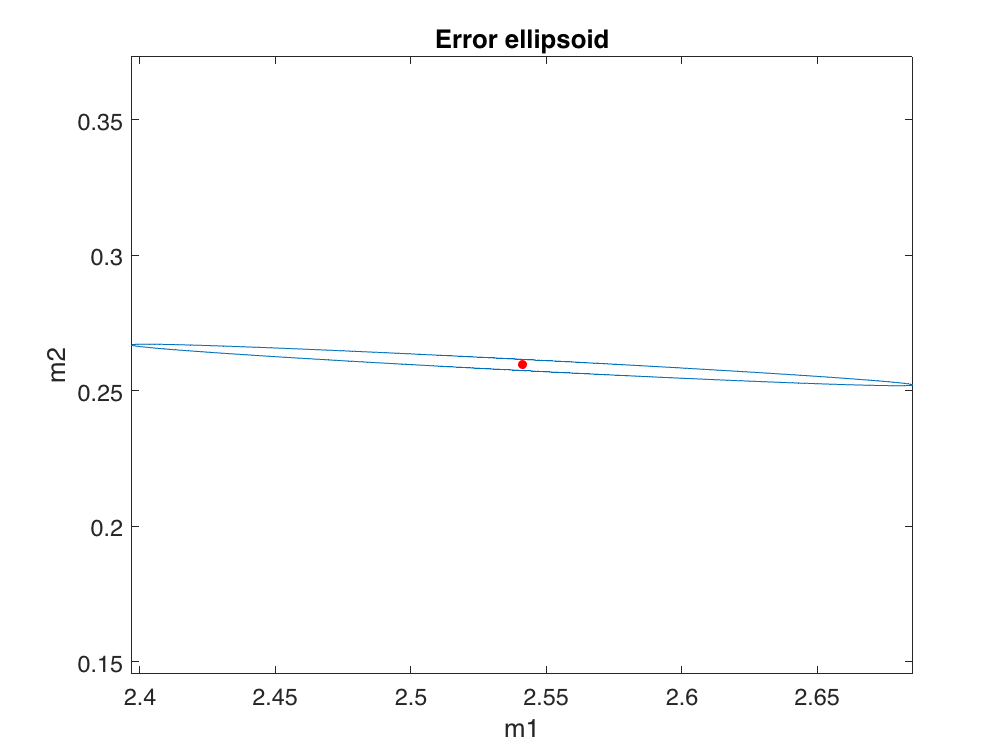

% linearized confidence ellipsoid
DELTA2 = chi2inv(0.95,2);

plot_ellipse(DELTA2,C,mest)
hold on
H=plot(mest(1),mest(2),'.r');
set(H,'markersize',15);
hold off
h_gc = gca;
h_gc.FontSize = 13;
xlabel('m1')
ylabel('m2')
title('Error ellipsoid')

2. Write your own code that use Levenberg-Marquardt method to fit the data.

(a) Choose initial parameter estimates $m_1 = 1.7, m_2 = 0$

m0 = [1.7;0]; % initial parameter estimates
step = 0.2;  % step size of the value of lambda in (0,1)
nlamb = 1; % number of values of lambda 
% call Levenberg-Marquardt method function
[mest_LM, iter1,lambda2] = Levenberg_Marquardt(m0,mxit,step,tol,nlamb)

mest_LM =     2.5411
    0.2595


iter1 = 14

lambda2 = 0.2000

% Check the chi^2 value.

chi2 = norm(funy(mest_LM))^2;
pvalue = 1 - chi2cdf(chi2,length(t)-2);
disp(['The estimate m1 = ',num2str(mest_LM(1)),', m2 = ', num2str(mest_LM(2)), ...
    '. The chi squared is ', num2str(chi2), ' which gives a p-value of ',num2str(pvalue)])

The estimate m1 = 2.5411, m2 = 0.2595. The chi squared is 2.8814e-07 which gives a p-value of 1


(b) Choose initial parameter estimates $m_1 = 1.6,m_2 = 0$

m0 = [1.6;0]; % initial parameter estimates
step = 0.2;  % step size of the value of lambda in (0,1)
nlamb = 2; % number of values of lambda 
% call Levenberg-Marquardt method function
[mest_LM, iter,lambda] = Levenberg_Marquardt(m0,mxit,step,tol,nlamb)

mest_LM =     2.5411    2.5411
    0.2595    0.2595


iter =     13     1


lambda =     0.2000    0.4000


function [m, iter] = Gauss_Newton(m0,mxit,tol)
    
    global Jacb2; global funy;
    
    iter = 0;
    
    for i = 1: mxit
        
        Jm = Jacb2(m0);
        Ym = funy(m0);
        Dm = -(Jm'*Jm)\(Jm'*Ym);
        
        m = m0 + Dm;
        iter = iter + 1;
        
        if(norm(Dm) < tol)
            break 
        end
        m0 = m;
    end
    
end

function plot_ellipse(DELTA2,C,m) 

    n=10000;
    
    %construct a vector of n equally-spaced angles from (0,2*pi)
    theta = linspace(0,2*pi,n)';
    %corresponding unit vector
    xhat = [cos(theta),sin(theta)];
    Cinv = inv(C);
    %preallocate output array
    r=zeros(n,2);
    for i=1:n
      %store each (x,y) pair on the confidence ellipse
      %in the corresponding row of r
      r(i,:)=sqrt(DELTA2/(xhat(i,:)*Cinv*xhat(i,:)'))*xhat(i,:);
    end
    %
    % Plot the ellipse and set the axes.
    %
    plot(m(1)+r(:,1), m(2)+r(:,2));
    axis equal
end

function [mest, iter, lambda] = Levenberg_Marquardt(m0,mxit,step,tol,nlamb)
    
    global Jacb2; global funy;
    
    lam = 0+step:step:1-step;
    n = length(m0);
    done = 0;
    lambda = []; iter = []; mest = [];
    
    for j = 1:length(lam)
        
        lamb = lam(j);
        iterj = 0;
        
        for i = 1: mxit
            
            Jm = Jacb2(m0);
            Ym = funy(m0);
            Dm = -(Jm'*Jm + lamb*eye(n))\(Jm'*Ym);
            
            m = m0 + Dm;
            iterj = iterj + 1;
            
            if(norm(Dm) < tol)
                done = done + 1;
                iter = [iter,iterj];
                lambda = [lambda,lamb];
                mest = [mest,m];
                break 
            end
            m0 = m;
            
        end
        
        if(done == nlamb)
            return 
        end
    end    
    
end
